## Equipo 3: Imperio SIUUU

## Inciso B) Caminata aleatoria 

clear;
N = 10000; % Numero de experimentos
t = 100000; % Cantidad de movimientos

rng("default")

experimentos = zeros(N,t);

for jj = 1:N %Ciclo for para ejecutar todos los experimentos
    pd = makedist("Uniform",0,1);
    movimientos = round(random(pd,1,t));
    posicion = zeros(1,t);
    for ii = 2:t % Ciclo for para ejecutar cada experimento individualmente
        if movimientos(ii) == 0
            posicion(ii) = posicion(ii-1) - 1;
        else
            posicion(ii) = posicion(ii-1) + 1;
        end
    end
    experimentos(jj,1:t) = posicion; % Guardar resultado de cada experimento
end
% Vamos a analizar los datos

mean(experimentos(1:N,t))
mean(abs(experimentos(1:N,t)))

## Inciso C) Modelo SIR determinístico

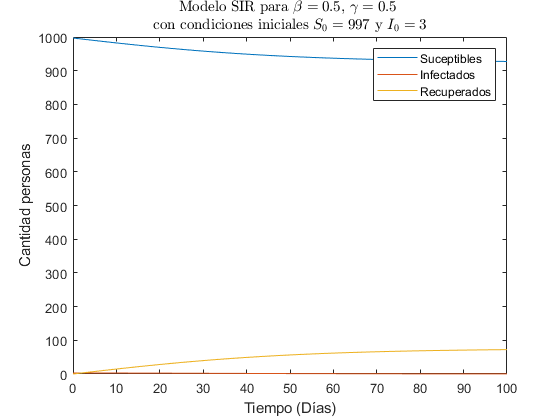

clear;

% Parámetros del sistema

N = 1000;  % Poblacion inicial
t = 1000;  % Dias a simular
bet = 0.5; % Parámetro beta
gam = 0.5; % Parámetro gamma


tspan = [0 100]; % Rango de tiempo
y0 = [997 3 0];  % Condiciones iniciales S_0, I_0, R_0
[t,y] = ode45(@(t,y) odefcn(t,y,bet,gam,N), tspan, y0); % Solución del sistema de EDs

% Visualización de los resultados
plot(t,y(:,1),t,y(:,2),t,y(:,3))
legend('Suceptibles','Infectados','Recuperados')
title({'Modelo SIR para $\beta = 0.5$, $\gamma = 0.5$ ';
    'con condiciones iniciales $S_0=997$ y $I_0=3$'},'Interpreter','latex')
xlabel('Tiempo (Días)')
ylabel('Cantidad personas')

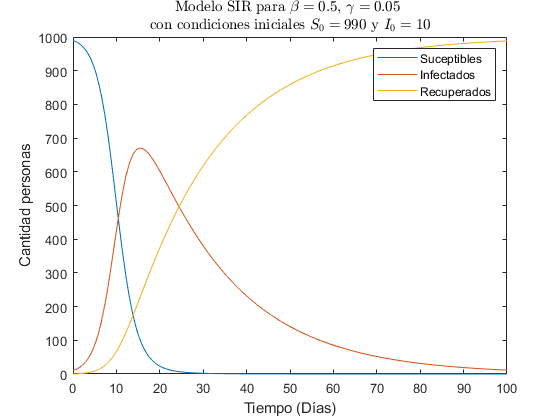

clear;

% Parámetros del sistema

N = 1000;  % Poblacion inicial
t = 1000;  % Dias a simular
bet = 0.5; % Parámetro beta
gam = 0.05; % Parámetro gamma


tspan = [0 100]; % Rango de tiempo
y0 = [990 10 0];  % Condiciones iniciales S_0, I_0, R_0
[t,y] = ode45(@(t,y) odefcn(t,y,bet,gam,N), tspan, y0); % Solución del sistema de EDs

% Visualización de los resultados
plot(t,y(:,1),t,y(:,2),t,y(:,3))
legend('Suceptibles','Infectados','Recuperados')
title({'Modelo SIR para $\beta = 0.5$, $\gamma = 0.05$ ';
    'con condiciones iniciales $S_0=990$ y $I_0=10$'},'Interpreter','latex')
xlabel('Tiempo (Días)')
ylabel('Cantidad personas')

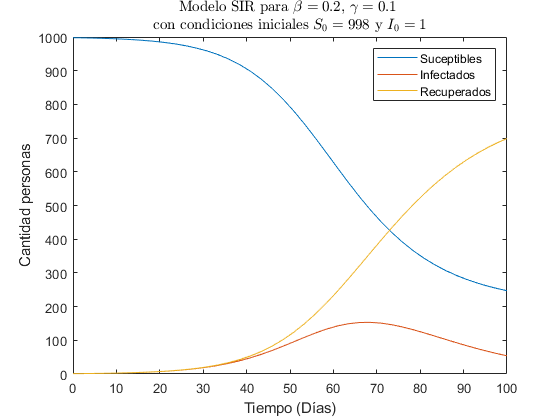

clear;

% Parámetros del sistema

N = 1000;  % Poblacion inicial
t = 100;  % Dias a simular
bet = 0.2; % Parámetro beta
gam = 0.1; % Parámetro gamma


tspan = [0 100]; % Rango de tiempo
y0 = [998 1 1];  % Condiciones iniciales S_0, I_0, R_0
[t,y] = ode45(@(t,y) odefcn(t,y,bet,gam,N), tspan, y0); % Solución del sistema de EDs

% Visualización de los resultados
plot(t,y(:,1),t,y(:,2),t,y(:,3))
legend('Suceptibles','Infectados','Recuperados')
title({'Modelo SIR para $\beta = 0.2$, $\gamma = 0.1$ ';
    'con condiciones iniciales $S_0=998$ y $I_0=1$'},'Interpreter','latex')
xlabel('Tiempo (Días)')
ylabel('Cantidad personas')

function dydt = odefcn(t,y,bet,gam,N) % Sistema de EDs del modelo SIR
  dydt = zeros(3,1);
  dydt(1) = -bet*y(2).*y(1)/N;
  dydt(2) = bet*y(2).*y(1)/N - gam*y(2);
  dydt(3) = gam*y(2);
end